## LAB 12 SNS

## Syed Sualeh Abbas 10303

% Task 1: 
% Computing Laplace Transforms and then Inverse Transforms
clear; clc;

% Create symbolic objects for algebraic calculations
syms t s

%% Signal x1 = u(t)
x1 = heaviside(t); %'heaviside' for unit step u(t)
X1 = laplace(x1, t, s); 
x1_verify = ilaplace(X1, s, t);

fprintf('Signal 1: u(t)\n');

Signal 1: u(t)


disp('Laplace Transform X1(s):');

Laplace Transform X1(s):


disp(X1);

$$\frac{1}{s}$$

disp('Verified Inverse x1(t):');

Verified Inverse x1(t):


disp(x1_verify);

$$1$$


%% Signal x2 = e^(-2t)u(t)
%  to ensure the signal is causal (t >= 0), we will multiply it with heavyside.
x2 = exp(-2*t) * heaviside(t); 
X2 = laplace(x2, t, s);
x2_verify = ilaplace(X2, s, t);

fprintf('\nSignal 2: e^(-2t)u(t)\n');


Signal 2: e^(-2t)u(t)


disp('Laplace Transform X2(s):');

Laplace Transform X2(s):


disp(X2);

$$\frac{1}{s+2}$$

disp('Verified Inverse x2(t):');

Verified Inverse x2(t):


disp(x2_verify);

$${\mathrm{e}}^{-2\,t}$$


%% Signal x3 = delta(t)
x3 = dirac(t); % 'dirac' is unit impulse delta function
X3 = laplace(x3, t, s);
x3_verify = ilaplace(X3, s, t);

fprintf('\nSignal 3: delta(t)\n');


Signal 3: delta(t)


disp('Laplace Transform X3(s):');

Laplace Transform X3(s):


disp(X3);

$$1$$

disp('Verified Inverse x3(t):');

Verified Inverse x3(t):


disp(x3_verify);

$$\delta (t)$$

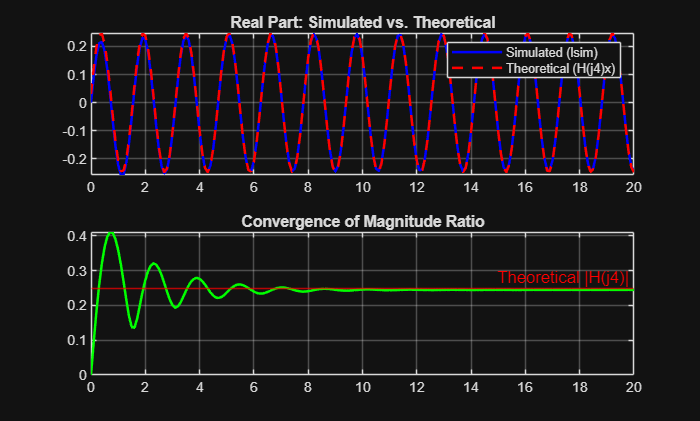

% Task 2:
clear; clc;

%% Define the System
num = [1];          % 1 is the numerator
den = [1 0.5];      % Represents s + 0.5, this will be denominator
sys = tf(num, den); % This creates the Transfer Function object 'sys'

%% Define Input x(t) = e^(j4t)
t = 0:0.1:20;       
w = 4;              % Angular frequency (4 rad/s)
x = exp(1j * w * t); % Complex exponential input

%% Computing Outputs
% lsim calculates the actual system response.
y_sim = lsim(sys, x, t);

% evalfr evaluates H(s) at s=j4 to get theoretical steady state gain
H_j4 = evalfr(sys, 1j * w); 
y_theory = H_j4 * x; %'shortcut' prediction

%% plotting
figure;

% Subplot 1: Real Part Comparison
subplot(2,1,1);
plot(t, real(y_sim), 'b', 'LineWidth', 1.5); hold on;
plot(t, real(y_theory), 'r--', 'LineWidth', 1.5);
title('Real Part: Simulated vs. Theoretical');
legend('Simulated (lsim)', 'Theoretical (H(j4)x)');
grid on;

% Subplot 2: Magnitude Ratio
subplot(2,1,2);
mag_ratio = abs(y_sim ./ x.'); % Element wise division to find gain for each point
plot(t, mag_ratio, 'g', 'LineWidth', 1.5); hold on;
yline(abs(H_j4), 'r', 'Theoretical |H(j4)|'); 
title('Convergence of Magnitude Ratio');
grid on;

% Task 3: 
clear; clc;

%% Part A & B: Time-Stepping Loop
dt = 0.1;           % Time step size
t = 0:dt:1;         % Time vector for first 10 points
y_num = zeros(1, length(t)); 

% Impulse input x(t) = delta(t). 
% for t=0, impluse is represented as 1/dt so the area is 1.
x = zeros(1, length(t));
x(1) = 1/dt; 

% Differential Equation: dy/dt = x(t) - 2y(t)
% Iteration: y(n+1) = y(n) + dt * (x(n) - 2*y(n))
for n = 1:length(t)-1
    y_num(n+1) = y_num(n) + dt * (x(n) - 2*y_num(n));
end

%% Part C & D: 
syms s t_sym
% H(s) = 1 / (s + 2)
% For x(t) = delta(t), X(s) = 1. hence Y(s) = H(s) * 1
Y_s = 1 / (s + 2);
y_analytical_func = ilaplace(Y_s, s, t_sym);

% Evaluate analytical solution at the same time points
y_ana = double(subs(y_analytical_func, t_sym, t));

%% Part E: Comparison Table
% Display the first 10 steps 
Time_Points = t(1:10)';
Numerical_y = y_num(1:10)';
Analytical_y = y_ana(1:10)';

T = table(Time_Points, Numerical_y, Analytical_y);
fprintf('Comparison of Numerical Iteration vs. Analytical Laplace:\n');

Comparison of Numerical Iteration vs. Analytical Laplace:


disp(T);

    Time_Points    Numerical_y    Analytical_y
    ___________    ___________    ____________

          0                0              1   
        0.1                1        0.81873   
        0.2              0.8        0.67032   
        0.3             0.64        0.54881   
        0.4            0.512        0.44933   
        0.5           0.4096        0.36788   
        0.6          0.32768        0.30119   
        0.7          0.26214         0.2466   
        0.8          0.20972         0.2019   
        0.9          0.16777         0.1653   



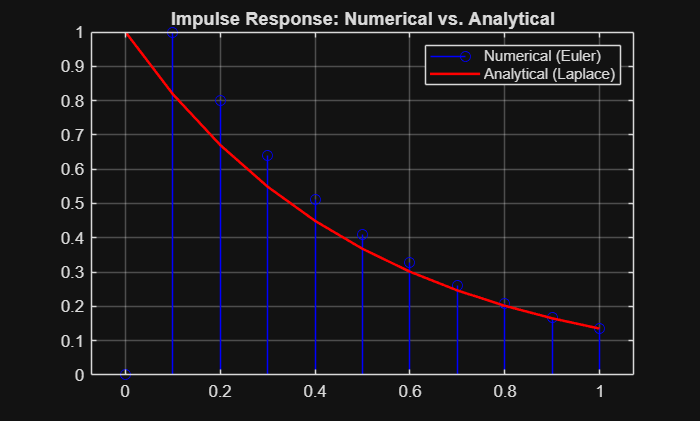

% Plot to see the decay
figure;
stem(t, y_num, 'b', 'DisplayName', 'Numerical (Euler)'); hold on;
plot(t, y_ana, 'r', 'LineWidth', 1.5, 'DisplayName', 'Analytical (Laplace)');
title('Impulse Response: Numerical vs. Analytical');
legend; grid on;

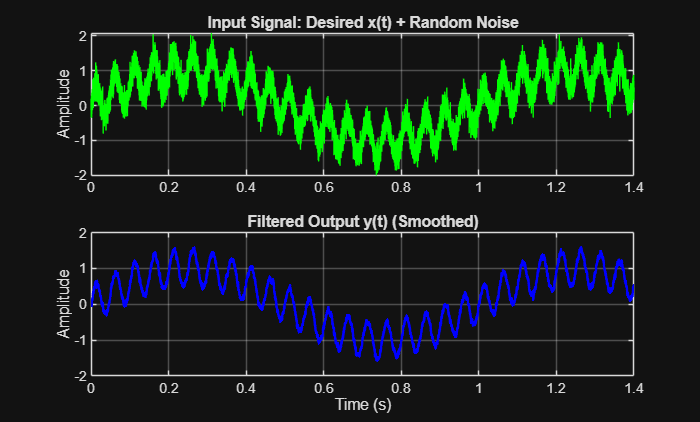

% Task 4:
clear; clc;

%% System Parameters
R = 1000;          % resistor
C = 1e-6;          % capacitor
RC = R * C;        
sys = tf(1, [RC 1]); 

%% Generating Signals
t = 0:0.0001:1.4; 

% The Signal x(t) provided in the lab manual
x_clean = sin(2*pi*t) + 0.5*sin(40*pi*t);

%Random noise signal is added:
noise = 0.2 * randn(size(t)); 
x_noisy = x_clean + noise;

%% Filtering the Signal
y_filtered = lsim(sys, x_noisy, t);

%% Plotting
figure;

subplot(2,1,1);
plot(t, x_noisy, 'g');
title('Input Signal: Desired x(t) + Random Noise');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
plot(t, y_filtered, 'b', 'LineWidth', 1.5);
title('Filtered Output y(t) (Smoothed)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;